%PID discretize with incremental PID
%sampling time 1ms，control output limit [-3,3],
clc;clear all
ts=0.001;                 %sampling time
sys=tf(50,[0.125,7, 0]); % system G（s）=50/(0.125s^2+7s),

dsys=c2d(sys,ts,'z');    %discretize so dsys is Y(z)/U(z)
[num,den]=tfdata(dsys,'v');% get num and den after discretize
% y       num(1)*z + num(2)
%---- = ---------------- ----
% u       den(1)*z + den(2)

u_1=0.0;
u_2=0.0;
y_1=0.0;
y_2=0.0;
x=[0,0,0]';
error_1=0;
error_2=0;

kp=6.5;ki=0.1;kd=0; 

S = input('What reference? 1=step; 2=sine----')

S = 1

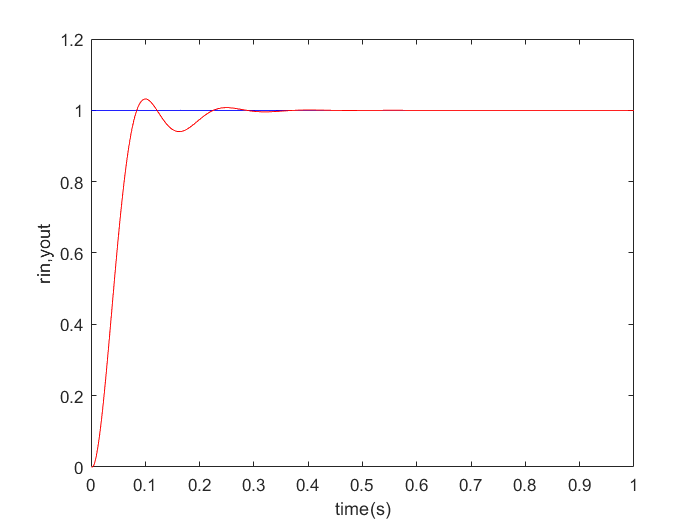

for k=1:1:1000
    time(k)=k*ts;                        %samplign time
    if S==1                              %step response
        rin(k)=1;                        %Step Signal
    elseif S==2                          %sine input
        rin(k)=0.5*sin(2*pi*k*ts);       %Sine Signal 
    end
    %Linear model ; convert TF to difference equation
    yout(k)=-den(2)*y_1-den(3)*y_2+num(2)*u_1+num(3)*u_2; % output
    error(k)=rin(k)-yout(k);                        % error

    % incremental PID
    du(k)=kp*x(1)+kd*x(2)+ki*x(3);       %PID Controller   
    u(k)=u_1+du(k);                      %u to the system
    if abs(u(k))>=3 u(k)=sign(u(k))*3; end                        % set limit
    

    u_2=u_1;                                        %save for next calculation
    u_1=u(k);                                       %save for next calculation
    y_2=y_1;                                        %save for next calculation
    y_1=yout(k);                                    %save for next calculation
    
    x(1)=error(k)-error_1;                          %KP part
    x(2)=error(k)-2*error_1+error_2;                %KD part
    x(3)=error(k);                                  %KI part
    error_2=error_1;                                %store error
    error_1=error(k);                               %store error
end


figure(1);
plot(time,rin,'b',time,yout,'r');               %reference and output
xlabel('time(s)'),ylabel('rin,yout');

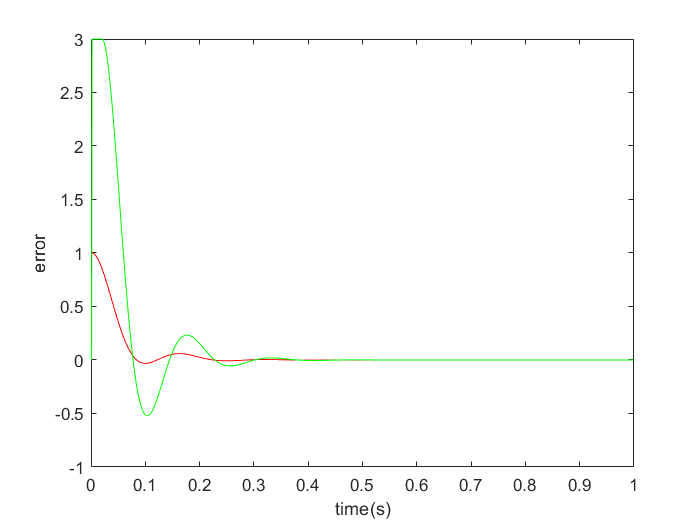

figure(2);
plot(time,error,'r',time,u,'g')                            %error
xlabel('time(s)');ylabel('error')